# Result Analyzde All Neurons

close all;clear;clc;
addpath models/
load data/data_rat010_0615_spike_train_top_9.mat
load results/baseline-top9-neurons.mat
load results/ANN_top_9_neurons.mat
load results\DBRccStatistical.mat;

2,15,9对应的一组参数的拟合结果是常数，ban掉

ANN_all_neurons(2,15,9).DBR

ans = 1.9311

ANN_all_neurons(2,15,9).DBR=Inf;

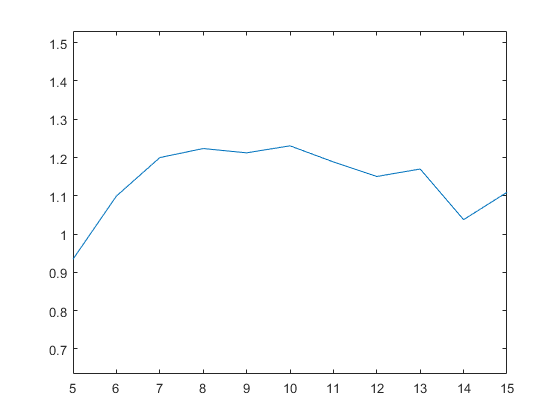

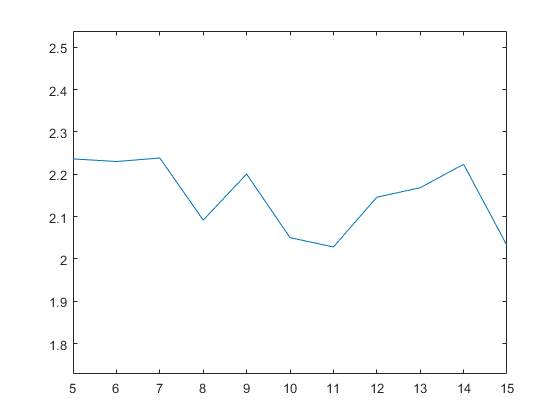

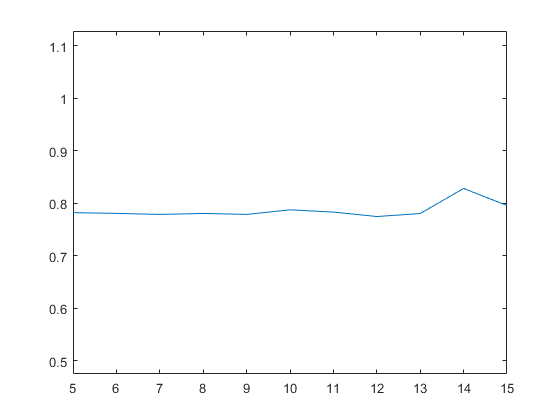

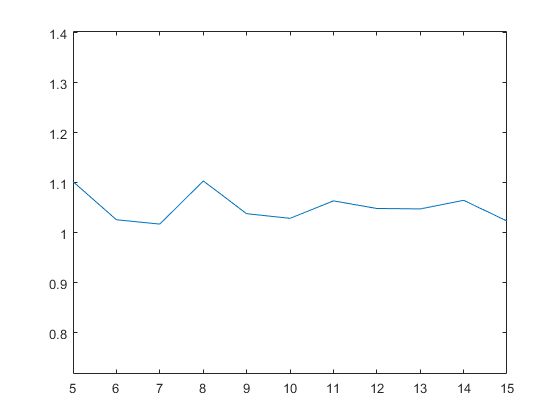

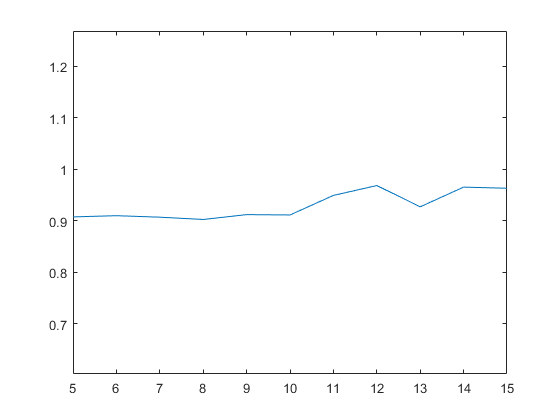

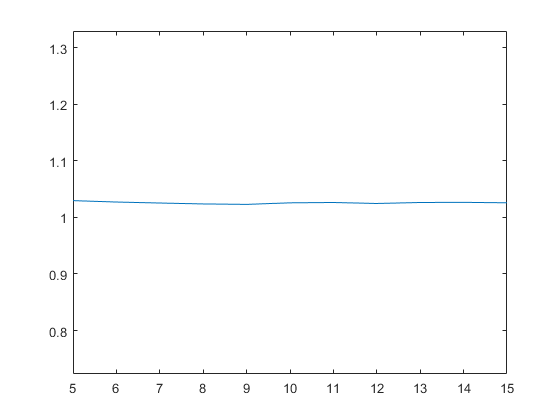

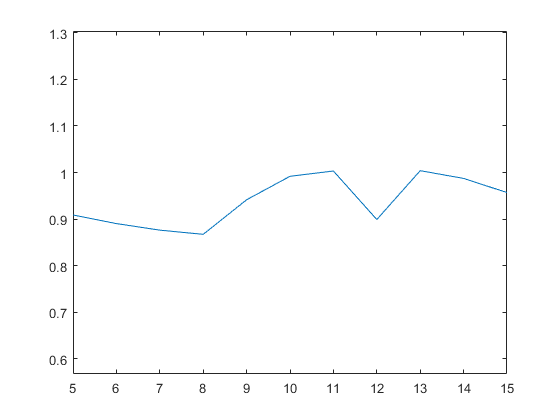

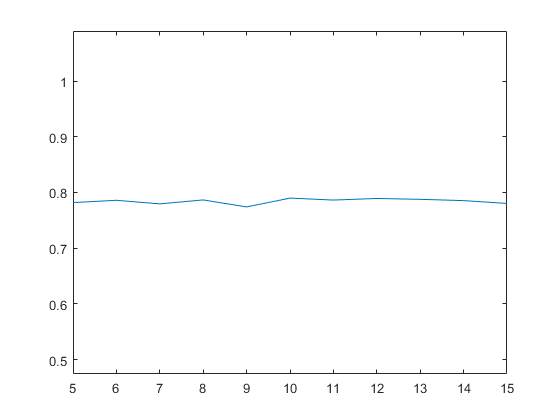

optimalNz = zeros(1,9);
optimalNzIdx = zeros(1,9);
for M1Idx=1:9
  ANN_neuron = squeeze(ANN_all_neurons(M1Idx,:,:));
  ANN_Nz_DBR = zeros(1, 15);
  for Nz=5:15
    ANN_DBR_list = getFieldArray(ANN_neuron, "DBR", Nz);
    ANN_Nz_DBR(Nz)=min(ANN_DBR_list);
  end
  [~,optimalNz(M1Idx)] = min(ANN_Nz_DBR(5:15));
  optimalNz(M1Idx) = optimalNz(M1Idx)+4;
  ANN_DBR_list = getFieldArray(ANN_neuron, "DBR", optimalNz(M1Idx));
  [~,optimalNzIdx(M1Idx)] = min(ANN_DBR_list);
  figure
  plot(5:15, ANN_Nz_DBR(5:15))
  ylim([min(ANN_Nz_DBR(5:15))-0.3, max(ANN_Nz_DBR(5:15))+0.3])
end

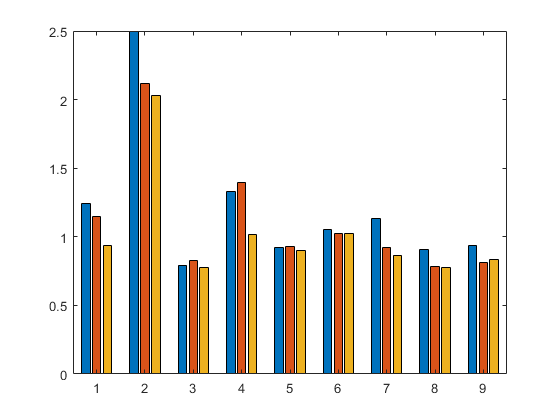

neurons_DBR = neurons_DBR(1:end,1:end);
for i=1:9
  neurons_DBR(3, i) = ANN_all_neurons(i, optimalNz(i), optimalNzIdx(i)).DBR;
end
figure
bar(neurons_DBR')

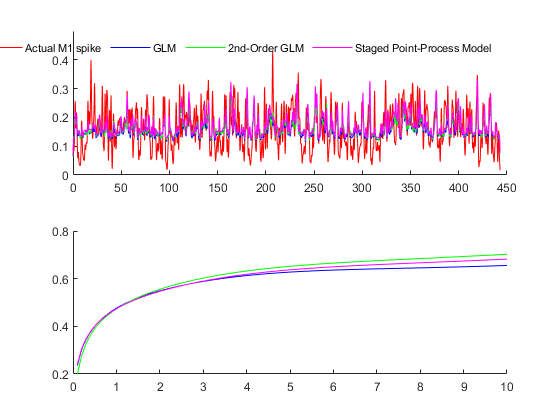

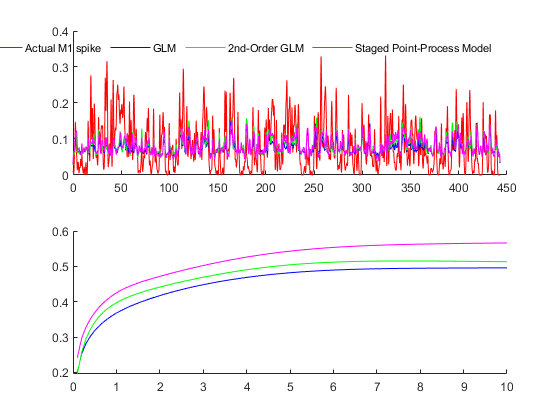

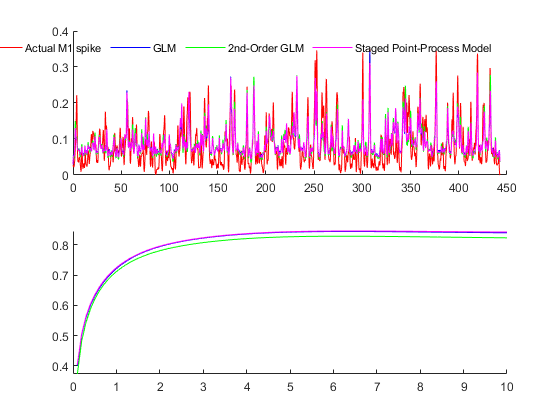

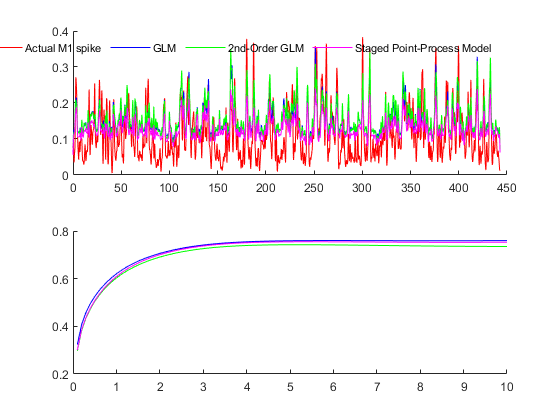

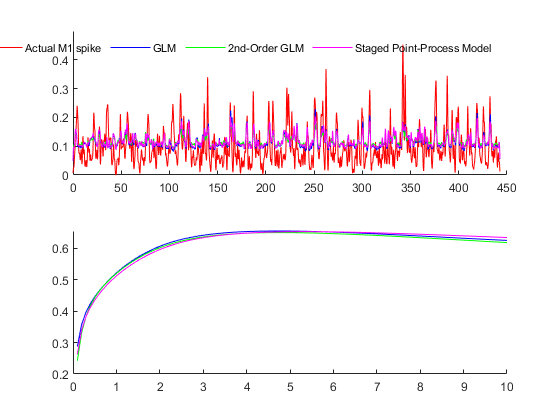

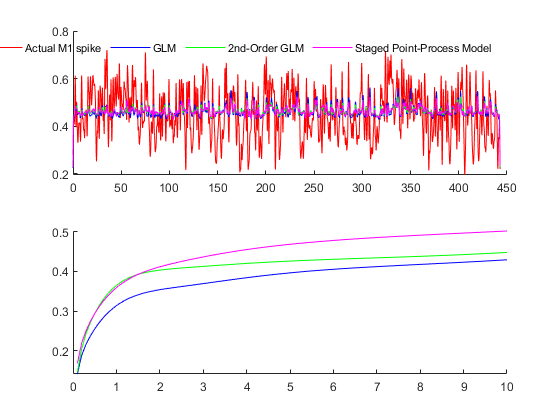

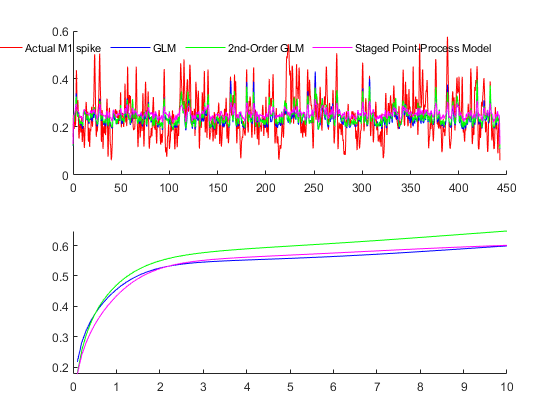

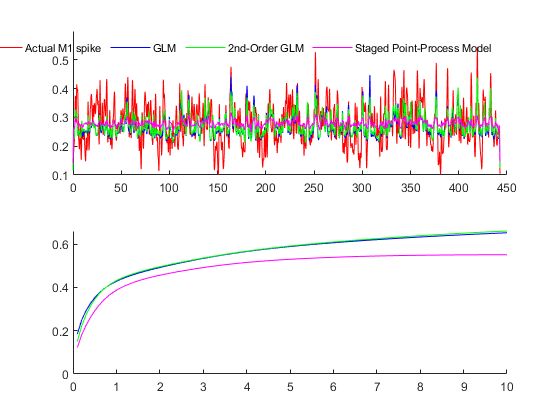

neurons_cc = neurons_cc(1:end,1:end);
for i=1:9
  mPFCspikePart = mPFCspike(:,mPFCm1Map(i,:)); % corresponding mPFC neurons
  M1spikePart = M1spike(:,i); % current M1 neuron
  delay = M1delay(i);
  % GLM
  W     = GLM_all_neurons(i).W;
  H     = GLM_all_neurons(i).H;
  [~,~,~,~,~,testX,~,~,testY] = splitDataAdvance(1,mPFCspikePart,M1spikePart,eventTrain,delay,segTrain,H);
  GLMtestLambdaYpre = GLMmodel(testX, W);
  GLMccListTest = zeros(1, 1000/10);
  % smooth result
  for kernelSize=10:10:1000
    smoothedLambda    = gaussianSmooth(testY, kernelSize);
    smoothedLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
    cc = corrcoef(smoothedLambda, smoothedLambdaPre);
    GLMccListTest(kernelSize/10) = cc(2);
  end
  % GLM sec
  W        = GLM_sec_all_neurons(i).W;
  H        = GLM_sec_all_neurons(i).H;
  lagnum   = GLM_sec_all_neurons(i).lagnum;
  lagalpha = GLM_sec_all_neurons(i).lagalpha;
  order = ['vm2-',num2str(lagnum),'-',num2str(lagalpha)];
  [~,~,~,~,~,testX,~,~,testY] = splitDataAdvance(order,mPFCspikePart,M1spikePart,eventTrain,delay,segTrain,H);
  GLMsectestLambdaYpre = GLMmodel(testX, W);
  GLM_sec_ccListTest = zeros(1, 1000/10);
  for kernelSize=10:10:1000
    smoothedLambda    = gaussianSmooth(testY, kernelSize);
    smoothedLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
    cc = corrcoef(smoothedLambda, smoothedLambdaPre);
    GLM_sec_ccListTest(kernelSize/10) = cc(2);
  end
  % ANN
  W     = ANN_all_neurons(i, optimalNz(i),optimalNzIdx(i)).W;
  M1Idx = ANN_all_neurons(i, optimalNz(i),optimalNzIdx(i)).M1Idx;
  Nz    = ANN_all_neurons(i, optimalNz(i),optimalNzIdx(i)).Nz;
  [~,~,~,~,~,testX,~,~,testY] = splitDataAdvance(1,mPFCspikePart,M1spikePart,eventTrain,delay,segTrain,H);
  [~, Nx] = size(testX);
  ANNtestLambdaYpre  = ANNmodel(testX,  W, Nx, Nz);
  ANNccListTest = zeros(1, 1000/10);
  % smooth
  for kernelSize=10:10:1000
    smoothedLambda    = gaussianSmooth(testY, kernelSize);
    smoothedLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);
    cc = corrcoef(smoothedLambda, smoothedLambdaPre);
    ANNccListTest(kernelSize/10) = cc(2);
  end
  
  kernelSize = 200;
  smoothedLambda = gaussianSmooth(testY, kernelSize);
  smoothedGLMLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
  smoothedGLMsecLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
  smoothedANNLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);

  cc = corrcoef(smoothedLambda, smoothedGLMLambdaPre);
  neurons_cc(1,i) = cc(2);
  cc = corrcoef(smoothedLambda, smoothedGLMsecLambdaPre);
  neurons_cc(2,i) = cc(2);
  cc = corrcoef(smoothedLambda, smoothedANNLambdaPre);
  neurons_cc(3,i) = cc(2);

  % plot
  spikeLength = length(testY);
  index = 1:spikeLength;
  t = index/100;
%   t = 200:0.01:300;
%   index = 20000:30000;
  h = figure("Name", ['top', num2str(i), 'neuron']);
  subplot(2,1,1)
  hold on
  plot(t, smoothedLambda(index), 'r');
  plot(t, smoothedGLMLambdaPre(index), 'b');
  plot(t, smoothedGLMsecLambdaPre(index), 'g');
  plot(t, smoothedANNLambdaPre(index), 'm');
  hold off
  legend("Actual M1 spike", "GLM", "2nd-Order GLM", "Staged Point-Process Model", "Box","off", "Orientation","horizontal")
  subplot(2,1,2)
  hold on
  plot(0.1:0.1:10, GLMccListTest, 'b')
  plot(0.1:0.1:10, GLM_sec_ccListTest, 'g')
  plot(0.1:0.1:10, ANNccListTest, 'm');
  hold off
%   savefig(h, ['results/top9/top', num2str(i), 'neuron.fig'])
end

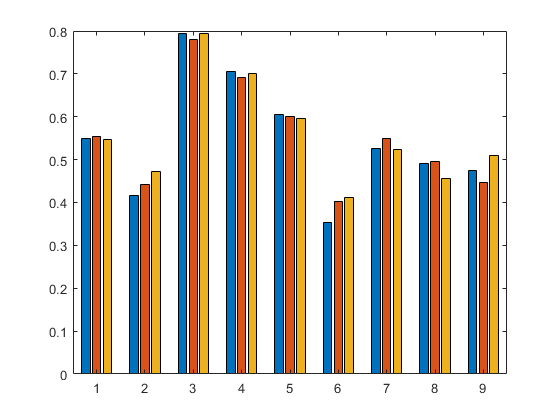

figure
bar(neurons_cc')

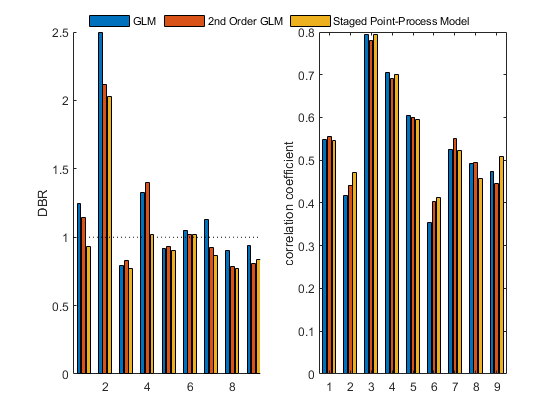

h = figure("Name", "Neurons-DBR-cc");
subplot(1,2,1)
hold on
bar(neurons_DBR');
plot(0.5:0.01:9.6, ones(1, 911), 'k:')
ylabel('DBR')
xlim([0.5 9.6])
hold off
xlim([0.5 9.3])
subplot(1,2,2)
bar(neurons_cc');
ylabel("correlation coefficient")
legend("GLM", "2nd Order GLM", "Staged Point-Process Model", "Position",[0.5  0.95  0  0], "Box","off", "Orientation","horizontal")

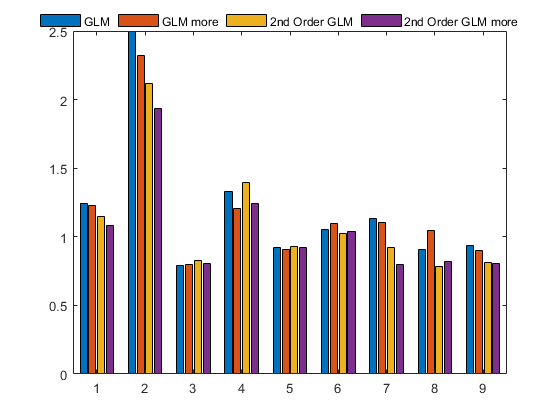

load results\DBRccStatistical.mat
compareDBR(1,:) = neurons_DBR(1,:);
compareDBR(3,:) = neurons_DBR(2,:);
compareCC(1,:) = neurons_cc(1,:);
compareCC(3,:) = neurons_cc(2,:);
load results\DBRccStatistical-mPFC-8.mat
compareDBR(2,:) = neurons_DBR(1,:);
compareDBR(4,:) = neurons_DBR(2,:);
compareCC(2,:) = neurons_cc(1,:);
compareCC(4,:) = neurons_cc(2,:);
figure
bar(compareDBR');
legend("GLM", "GLM more", "2nd Order GLM", "2nd Order GLM more", "Position",[0.5  0.95  0  0], "Box","off", "Orientation","horizontal")

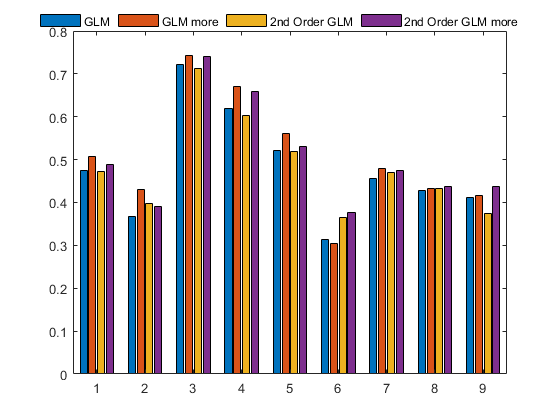

figure
bar(compareCC');
legend("GLM", "GLM more", "2nd Order GLM", "2nd Order GLM more", "Position",[0.5  0.95  0  0], "Box","off", "Orientation","horizontal")